## 1a

fs = 16000

fs = 16000

[x, fs] = audioread("ø6/sinus_pcm16000.wav")

x =     0.7071
    0.9239
    1.0000
    0.9239
    0.7071
    0.3827
         0
   -0.3827
   -0.7071
   -0.9239


fs = 16000


num_samples = length(x)

num_samples = 40001

duration = num_samples/fs

duration = 2.5001

#### Spill av lyden

%soundsc(x,fs,16)

## 1b

x41 = x(1:41)

x41 =     0.7071
    0.9239
    1.0000
    0.9239
    0.7071
    0.3827
         0
   -0.3827
   -0.7071
   -0.9239


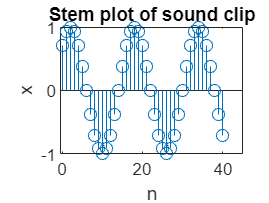

% Må flytte plottet til origo
stem(0:40, x41)
xlim([-0.5 45.0])
ylim([-1.00 1.00])
title('Stem plot of sound clip')
xlabel('n')
ylabel('x')

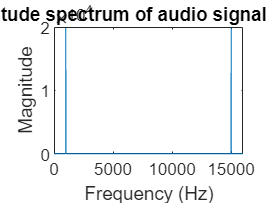


X = fft(x);

% Compute frequency axis
freq_axis = (0:length(x)-1) * fs / length(x);

% Plot magnitude spectrum
plot(freq_axis, abs(X));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude spectrum of audio signal fs=16000');

% 1g
fs = 16000;
[x, fs] = audioread("ø6/sinus_pcm16000.wav")

x =     0.7071
    0.9239
    1.0000
    0.9239
    0.7071
    0.3827
         0
   -0.3827
   -0.7071
   -0.9239


fs = 16000


new_fs = 8000;
x = resample(x, new_fs, fs);

soundsc(x,new_fs,16)

num_samples = length(x)

num_samples = 20001

duration = num_samples/fs

duration = 1.2501


x41 = x(1:41)

x41 =     0.5761
    1.0430
    0.6845
    0.0147
   -0.7166
   -0.9947
   -0.7114
    0.0019
    0.7062
    1.0011


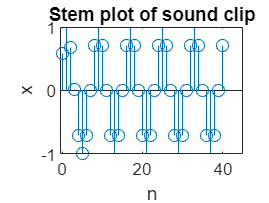

% Må flytte plottet til origo
stem(0:40, x41)
xlim([-0.5 45.0])
ylim([-1.00 1.00])
title('Stem plot of sound clip')
xlabel('n')
ylabel('x')

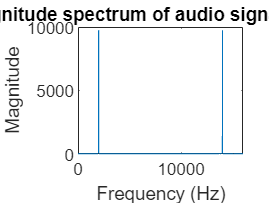


% Compute Fourier transform
X = fft(x);

% Compute frequency axis
freq_axis = (0:length(x)-1) * fs / length(x);

% Plot magnitude spectrum
plot(freq_axis, abs(X));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude spectrum of audio signal fs=8000');